clc;clear all;close all;
format long;
warning off;

**QUESTION 1**

m=50; n=12;
t=linspace(0,1,m)';
A=t.^(0:n-1);
f=cos(4*t);

%%% 1a %%%%%
Z = A'*A;
R = chol(Z);
c1=R\(R'\(A'*f));

%%% 1b %%%%%

[Q1,R1]=GS(A);
c2=R1\(Q1'*f);

%%% 1c %%%%%

[Q2,R2]=MGS(A);
c3=R2\(Q2'*f);

%%% 1d %%%%%
[V3,R3]=house(A);
Q3=house2q(V3);
c4=R3\(Q3'*f);


%%% 1e %%%%%
[Q4,R4]=qr(A);
c5=R4\(Q4'*f);


%%%% 1f %%%%%%
[U,S,V] = svd(A,0);
S(S>0)=1./S(S>0);
c6 = (V*S*U')*f;


T= table(c1,c2,c3,c4,c5,c6,'VariableNames',{'Cholesky','GS','MGS','Householder','Matlab-qr','svd'})

T = 12×6 table
          Cholesky                   GS                     MGS                  Householder               Matlab-qr                   svd         
    ____________________    ____________________    ____________________    _____________________    _____________________    _____________________

       0.999999980992711        1.00001318251953       0.999999998520678         1.00000000099661         1.00000000099661         1.00000000099661
    5.27619096712327e-06    -0.00225720796770773    3.05080723622847e-07    -4.22743046597237e-07    -4.22742854814656e-07    -4.22742847265887e-07
       -8.00019212913028       -7.93913160486316       -8.00000853723398        -7.99998123568477        -7.99998123569083        -7.99998123569085
     0.00275327159368894      -0.6519167

writetable(T,"table.csv")

Next we compare the coefficients with those of the qr and set a tolerance of $10^{-8}$ to pick points that will be coloured in red.

find(abs(c1 - c5)> 10e-8) % Find index where the absolute difference is greater than 10e-8

ans =      2
     3
     4
     5
     6
     7
     8
     9
    10
    11


find(abs(c2 - c5)> 10e-8)

ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


find(abs(c3 - c5)> 10e-8)

ans =      2
     3
     4
     5
     6
     7
     8
     9
    10
    11


find(abs(c4 - c5)> 10e-8)


ans =

  0×1 empty double column vector



find(abs(c6 - c5)> 10e-8)


ans =

  0×1 empty double column vector



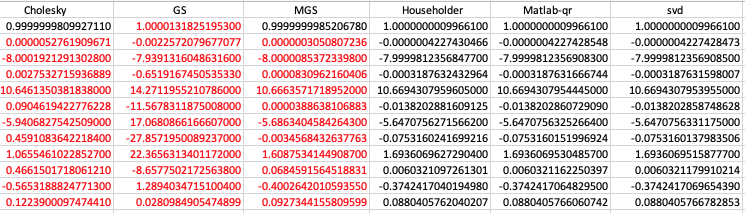

**Observation**

The figure above shows the values (coloured in red) that appear wrong. The qr coefficients were used as a yardstick for determining what is wrong or not . It can be observed that the clasisical Gram-Schmidt method (GS) is the most affected due to roundoff errors, next is the modified Gram-Schmidt and the Cholesky methods. Using a tolerance of $10^{-8}$ , the other methods appear to be right.  It appears that the Cholesky and qr looks  close to each other for the first four coefficients.

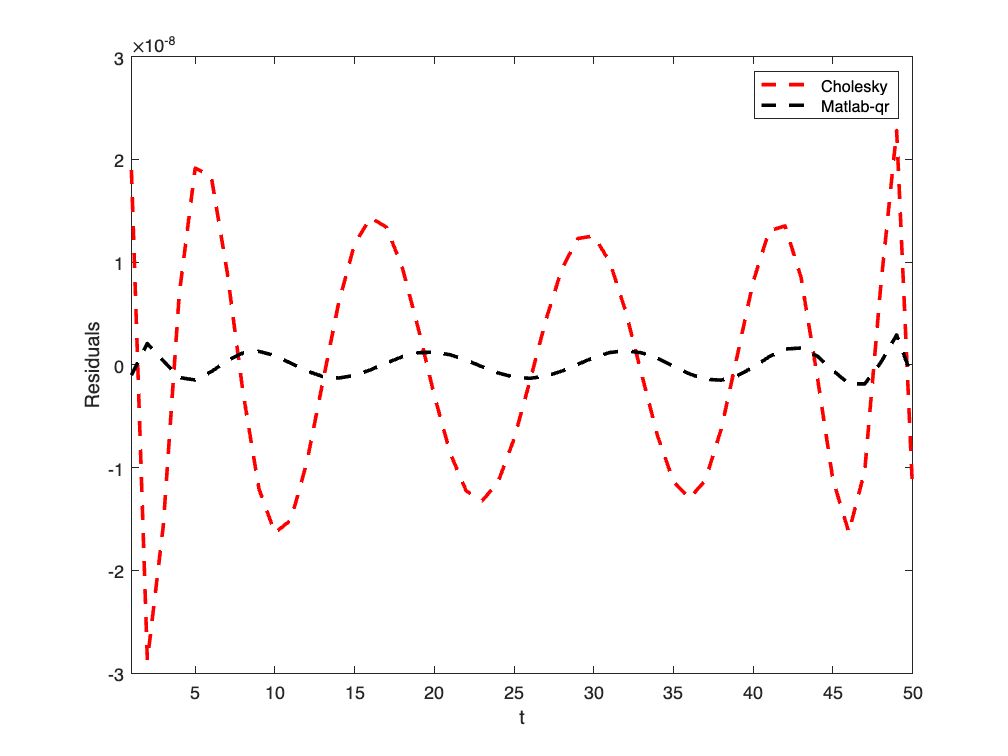

figure(1)

res10 = f-A*c1; % matlab Cholesky routine

res1 = f-A*c5;  % matlab qr routine

plot(res10,'--r', LineWidth=2), hold on

plot(res1,'--k', LineWidth=2)
xlim([1,size(f,1)])
legend('Cholesky', 'Matlab-qr')
xlabel('t')
ylabel('Residuals')

max(abs(res1))  % qr

ans =      2.919108399446202e-09


max(abs(res10)) % cholesky

ans =      2.879320337711988e-08


**observation**

From the Figure above and our observation of the maximum absolute residual  in the qr and cholesky methods which is approximately ${3e}^{-09}$  and ${3e}^{-08}$ respectively, the qr factorization provides a better approximation.

**Question 2**

%%%%%%%%%%%% 2a %%%%%%%%%%%%%%%%%%%%%%

${\|r\|}_w^2$ = ${\left(\textrm{Ax}-b\right)}^T W\left(\textrm{Ax}-b\right)$

         = ($x^T$$A^T$$-$ $b^T$)$W$$\left(\textrm{Ax}-b\right)$

        = $x^T A^T \textrm{WAx}$$-$$x^T A^T \textrm{Wb}$ $-$$b^T \textrm{WAx}$ $+$ $b^T \textrm{Wb}$

Taking the derivative with respect to x and equating to zero, we have;


$$\frac{d(||r||^2_w)}{dx}= 2A^TWA -A^TWb - b^TWA = 0$$


But, $A^T \textrm{Wb}$ = $b^T \textrm{WA}$

${2A}^T \textrm{WAx}$ = $2A^T \textrm{Wb}$

x = ${\left(A^T \textrm{WA}\right)}^{-1}$$A^T \textrm{Wb}$

%%%%%%%%%%%% 2b %%%%%%%%%%%%%%%%%%%%%%

W = zeros(m);
delta = 0.8;
for i = 1:m
    W(i,i) = exp(-(abs(1/23 - t(i))/delta)^2);
end

x_w = (A'*W*A)\(A'*W*f)  % weighted coefficients

x_w =    1.000000000430680
  -0.000000194863716
  -7.999990898790073
  -0.000162651213323
  10.668141631982348
  -0.007615972142881
  -5.665673569551202
  -0.039552661117411
   1.649483340002800
   0.039790819505998


% Compute the Vandermonde matrix at a fixed t  = 1/23

m=50; n=12;
t=(1/23)*ones(m,1); 
A=t.^(0:n-1);


P_weighted = A*x_w; % weighted polynomial
P_w_11 = P_weighted(11)

P_w_11 =    0.984915205156389


P_Non_weighted = A*c5;   % non weighted polynomial
P_11 = P_Non_weighted(11)

P_11 =    0.984915205008980


f_t = cos(4*1/23)

f_t =    0.984915205128733


**Comparing the weighted and non-weighted results**

abs(P_w_11 - f_t)      % Error in weighted least squares

ans =      2.765643269952989e-11


abs(P_11 - f_t)        % Error in non-weighted least squares

ans =      1.197527632612605e-10


From the results of the error produced by the weighted and non-weighted least squares, we can conclude that the weighted least squares produce a better approximation of $f(t) = cos(4t)$ at $t = 1/23$.

**Question 3**


$$\kappa = \frac{||J(X)||}{\frac{||f(x)||}{||x||}}$$



$$f(x) = \frac{log(x+1)}{x}$$



$$f^\prime(x) = \frac{x - (x+1)log(x+1)}{x^2(x+1)}$$



$$\kappa = \frac{|x -(x+1)log(x+1)|}{|(x+1)x^2|} \times \frac{|x^2|}{|log(x+1)|}$$



$$\kappa= \frac{|x - (x+1)log(x+1)|}{|(x+1)log(x+1)|}$$


%%%%%%%%%%%%% 3a  %%%%%%%%%%%%%%%%%%%%
kappa = @(x)abs(x-log(x+1)*(x+1))/abs(log(x+1)*(x+1));
x=-1e-7:1e-8:1e-7;
xk=zeros(size(x));
for i=1:length(xk)
    xk(i)= kappa(x(i));
end
xk

xk = 1.0e-07 *

   0.505263599926700   0.449095685898494   0.405263585164722   0.347333412191465   0.305263571961581   0.244161338618009   0.205263562964257   0.136759841598156   0.105263556518386   0.000247595009666                 NaN   0.010774707432576   0.150247593627234   0.163240158254519   0.194736437584337   0.233634201882727   0.313240143710505   0.352666585058642   0.394736414278106   0.438568501916138   0.505838629918435


**Observation**

It can be obsereved that the condition number of the points near zero are very small in the order of $10^{-7}$. Thus we can conclude that when the input is changed by a small amount, the corresponding output will be changed by a small amount.

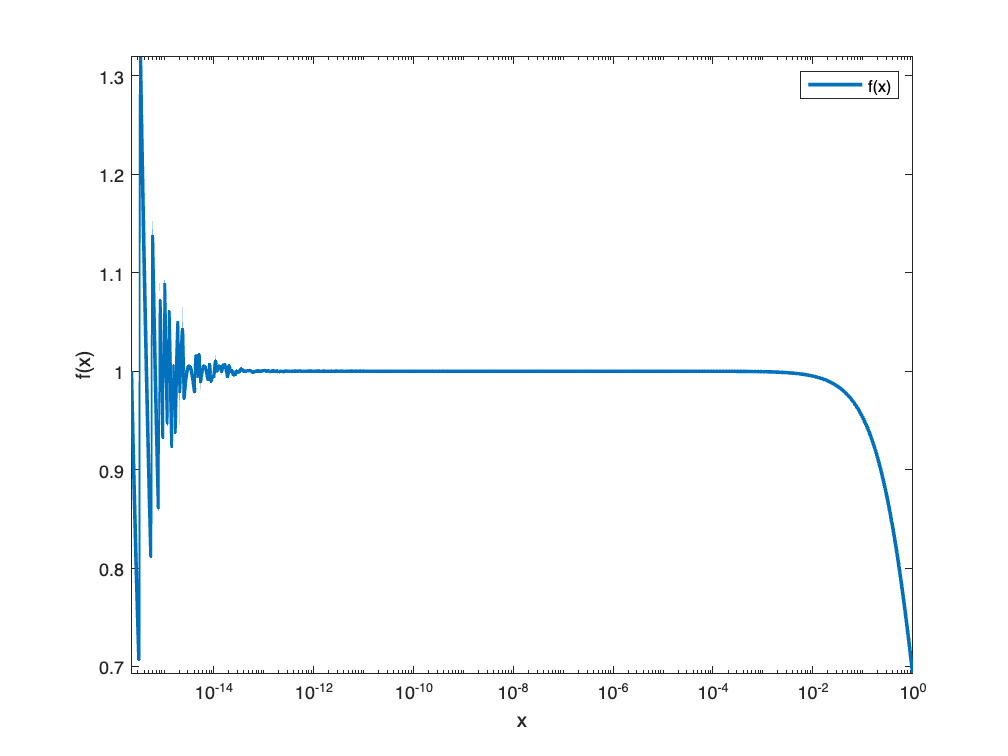

%%%%%%%%%%% 3b %%%%%%%%%%%%%%%%%
f=@(x)(log(x+1)./x);
j=0:1:520;
xj=2.^(-52+j./10);

figure(5)
semilogx(xj,f(xj), LineWidth=2)
xlabel('x')
ylabel('f(x)')
legend('f(x)')
axis tight

**Observation**

$f(x)$ appears to be unstable near x = 0.

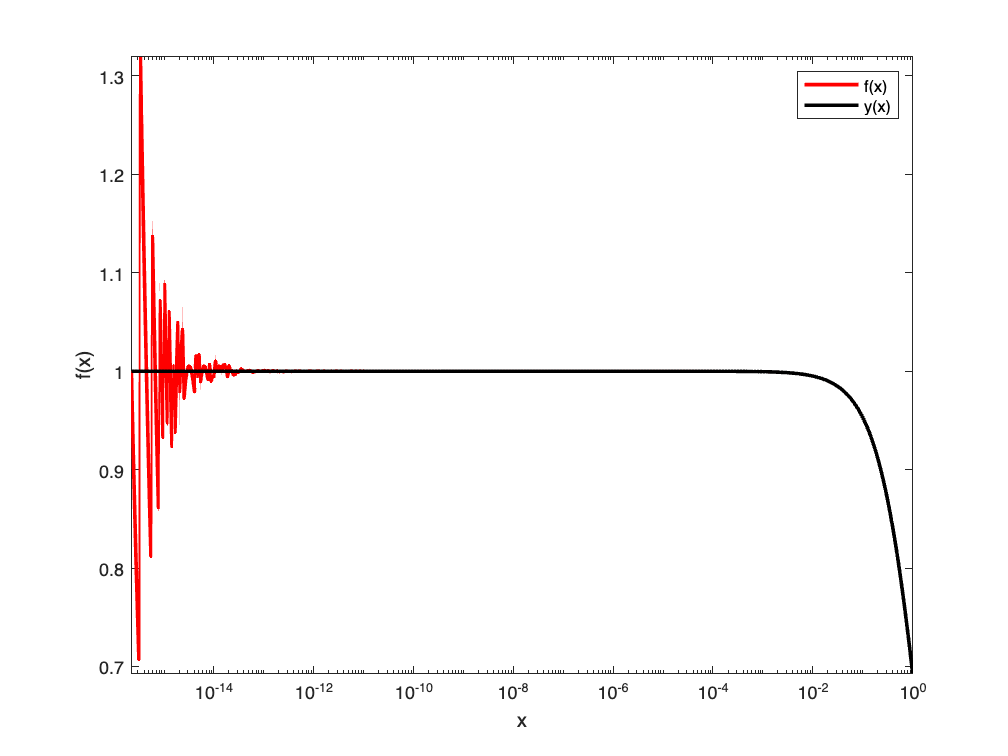

%%%%%%%%% 3c %%%%%%%%%%%%%%%
z =1+xj;
y = @(z)(log(z)./(z-1));

figure(6)

semilogx(xj,f(xj),'r',linewidth=2), hold on
semilogx(xj,y(z),'k',linewidth=2)
hold off;
xlabel('x')
ylabel('f(x)')
legend('f(x)','y(x)');
axis tight

**Observation**

$y(x)$appear to be stable near zero while $f(x)$ is unstable.

**Question 4**

%%%%%% 4a %%%%%%%%%%%%

Let us consider the equation, $\frac{||\delta x||}{||x||} \leq\kappa \frac{||r||}{||b||}$ 

Looking at the right hand side, we observe that $\kappa$ is the dominant factor in determining how the output will change with respect to a perturbation in the input. Thus we conclude that the size of the residual does not give us enough information about how close the solution is to the exact but the condition number  $\kappa$  does.

%%%%%% 4b %%%%%%%%%%%%

A = 1./hankel(2:6,6:10);
b = [0.882 0.744 0.618 0.521 0.447]';
x = A\b

x =   -2.519999999999232
   5.039999999991446
   2.520000000028753
   7.559999999962587
 -10.079999999983430


%%%%%% 4c %%%%%%%%%%%%

$A\hat{x}$= b + $\delta b$

$\hat{x}$ = $A^{-1} b$ + $A^{-1}$$\delta b$

$\hat{x}$ = x + $A^{-1}$$\delta b$

$\hat{x}$ = x + $\delta x$

$\delta x$ = $\hat{x}$  - x


kapp = cond(A)

kapp =      1.535043895304634e+06



% small pertubation of b

db = 1e-4:2.5e-5:2*1e-4;

x_cap = x + A\db';

dx =x_cap - x;

% Upper bound
kappa_db_b = kapp*norm(db)/norm(b)

kappa_db_b =      3.578889287846920e+02


dx_d=norm(dx)/norm(x)

dx_d =    0.171793173727223


**Observation**

First we observe that the condition number ($\kappa$) is really large and the product of the relative error in b and $\kappa$ is a lot greater than the relative error in x. This implies that a small perturbation in the input will lead to a large perturbation in the output.

**QUESTION 5**

n=30;
kapp = zeros(n,1)';
for i = 1:length(kapp)
    kapp(i) = cond(vandermonde(i,i));
end

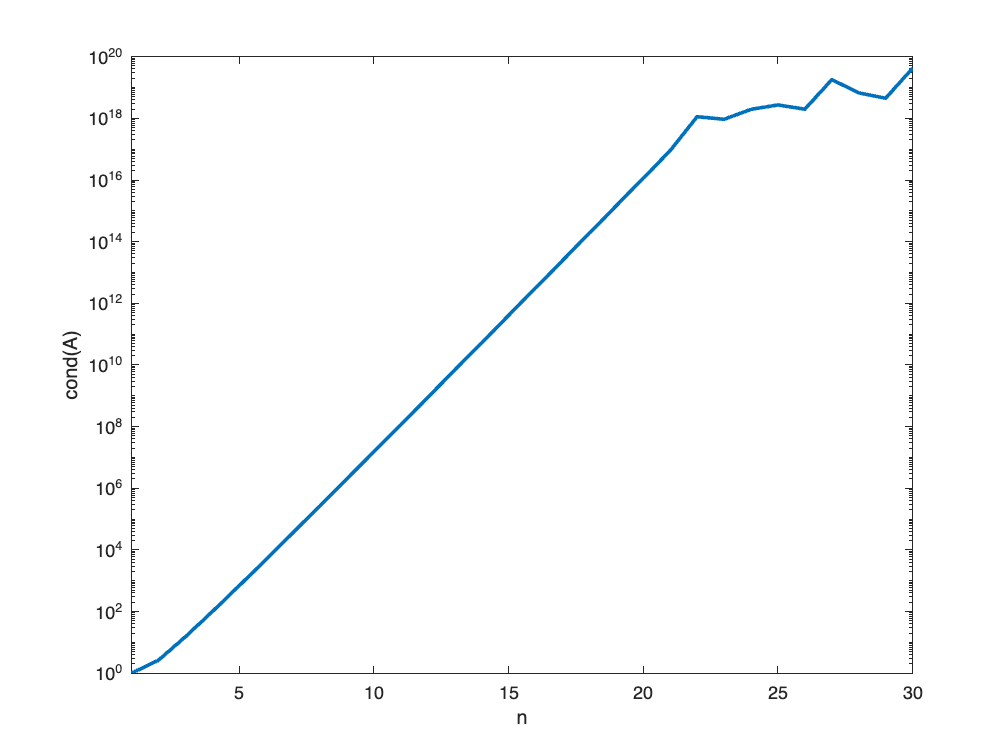


figure(7)
semilogy(1:1:n,kapp,linewidth=2)
xlim([1,30])
xlabel('n')
ylabel('cond(A)')

**Observation**

The condition number appears to grow linearly from n = 1 until n = 23 where it begins to fluctuate. This could be attributed to the intrinsic nature of the matrix which is ill-conditioned.

n=30;
kapp2 = zeros(n,1)';
for i = 1:length(kapp)
    kapp2(i) = cond(vandermonde(2*i-1,i));
end

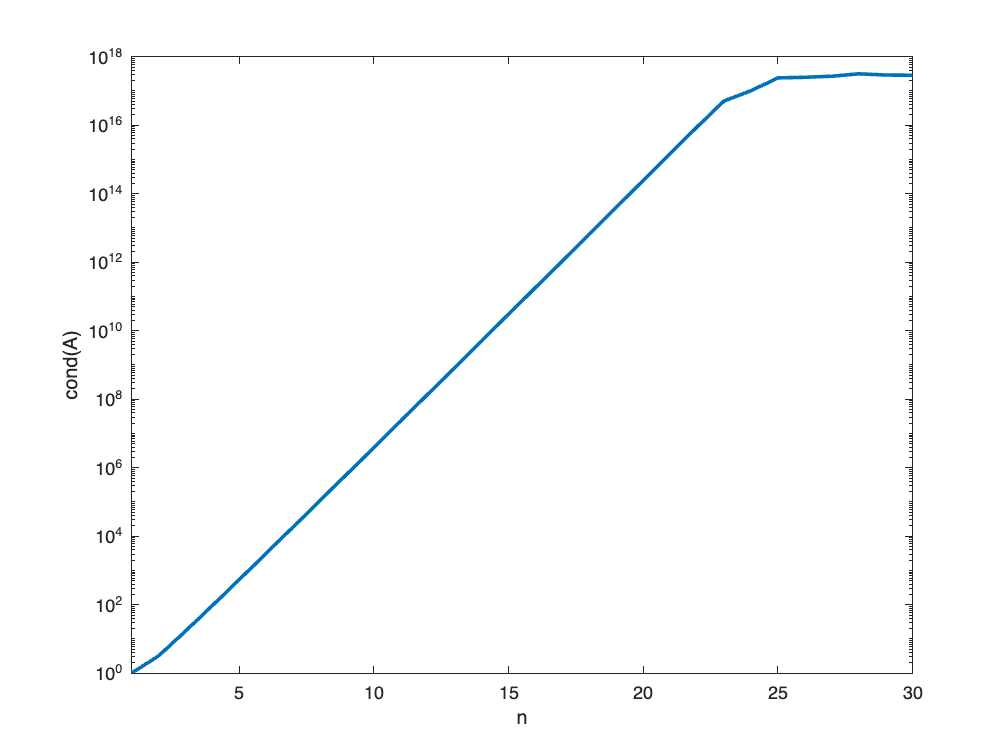

figure(8)
semilogy(1:1:n,kapp2,linewidth=2)
xlim([1,30])
xlabel('n')
ylabel('cond(A)')

**Observation**

The condition number appears to grow linearly from n = 1 until n = 25 where it reaches steady state. 

**QUESTION 6**

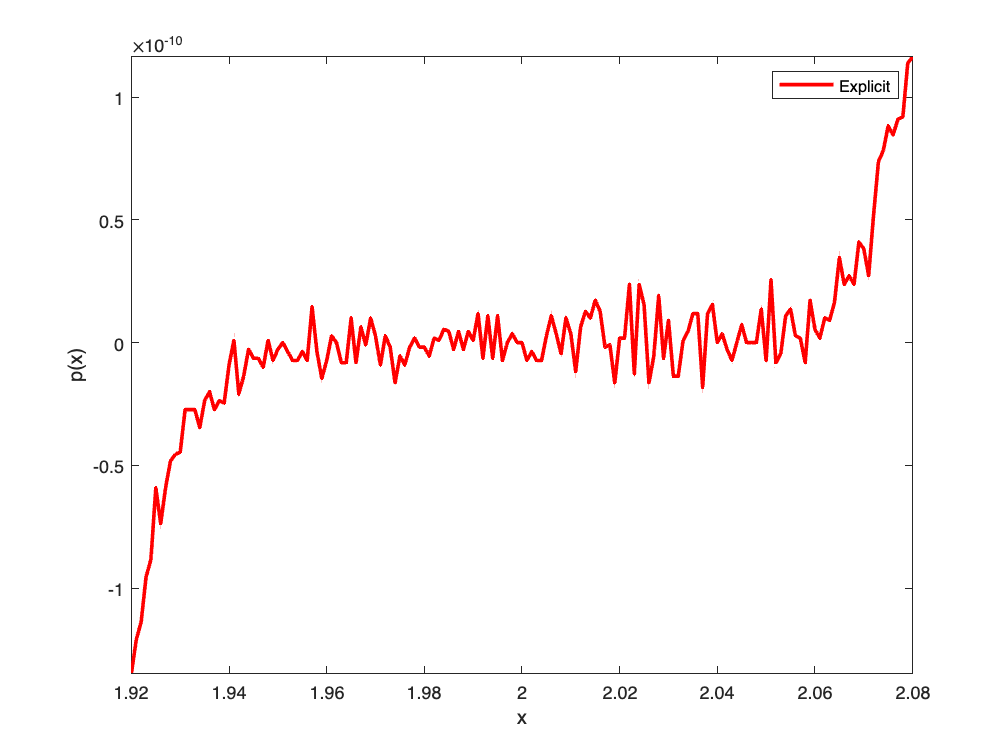

x=1.920:0.001:2.080;
r=zeros(size(x));
for i=1:length(x)
    r(i)=p(x(i));
end
figure(9)
plot(x,r,'r',LineWidth=2)
xlabel('x')
ylabel('p(x)')
legend('Explicit')
axis tight

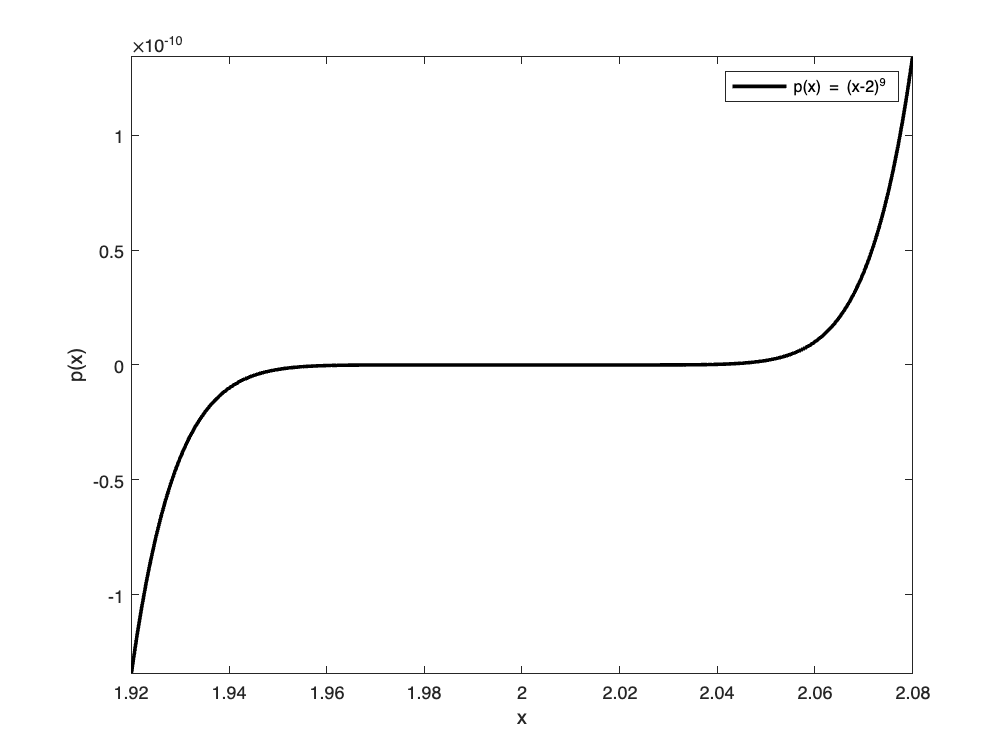

r_q=(x-2).^9;
figure(10)
plot(x,r_q,'k',LineWidth=2)
xlabel('x')
ylabel('p(x)')
legend('p(x) = (x-2)^9')
axis tight

**Observation**

We observe that the figure produced using $p(x) = (x-2)^9$ is smoother when compared to the figure obtained from the explicit expression of $p(x)$. This is due to the accumulation of roundoff errors in the explicit case.

**QUESTION 7**

P is a permutation matrix, it is orthogonal and symmetric. Thus $P^2$ = $P$.

P=zeros(10);
P(1,end) = 1; P(2,5) = 1; P(3,8) = 1; P(4,1) = 1;
P(5,4) = 1; P(6,9) = 1; P(7,2) = 1; P(8,3) = 1; P(9,6) = 1; P(10,7)= 1;


skeel_K = norm(P)

skeel_K =      1


Kappa_P = cond(P)

Kappa_P =      1


P(:,3)=10e-11*P(:,3);
skeel_K = norm(abs(inv(P))*abs(P))

skeel_K =      1


kappa_P = cond(P)

kappa_P =      1.000000000000000e+10


It can be observed that the skeel condition number is always less than or equal to $\kappa$ and it is invariant of the row or column scaling.

function  r = p(x)
    r = x^9 -18*x^8 + 144*x^7 - 672*x^6 + 2016*x^5 -4032*x^4 + 5376*x^3 - 4608*x^2 + 2304*x -512;
end

function A = vandermonde(m,n)
 t=linspace(0,1,m)';
 A=t.^(0:n-1);
end

function [V,R]=house(A)
[m, n]=size(A);
assert(m>=n,'The row count must be greater than or equal to the column count')
R=A;
V=zeros(m,n);
for k=1:n
    x=R(k:end,k);
    I=eye(m-(k-1));
    vk=x;
    vk(1)=vk(1)+sign(x(1))*norm(x);
    vk=vk/norm(vk);
    V(k:end,k)=vk;
    P=I-2*(vk*vk');
    R(k:end,k:n)=P*R(k:end,k:n);
end
end


function [Q]=house2q(V)
[m, n]=size(V);
assert(m>=n,'The row count must be greater than or equal to the column count')
Q=eye(m);
for k=n:-1:1
    Q(k:m,:) = Q(k:m,:) - 2*V(k:m,k)*(V(k:m,k)'*Q(k:m,:));
end
end




function [Q,R]=MGS(A)
[m, n]=size(A);
assert(m>=n,'The row count must be greater than or equal to the column count')
Q=zeros(m,n);
R=zeros(n,n);
for i=1:n
    vi=A(:,i);
    R(i,i)=norm(vi);
    Q(:,i)=vi/R(i,i);
    for j=i+1:n
        qi=Q(:,i);
        R(i,j)=qi'*A(:,j);
        A(:,j)=A(:,j)-R(i,j)*qi;

    end
end
end

function [Q,R]=GS(A)
[m, n]=size(A);
assert(m>=n,'The row count must be greater than or equal to the column count')
Q=zeros(m,n);
R=zeros(n,n);
for j=1:n
    aj=A(:,j);
    vj=aj;
    for i=1:j-1
        qi=Q(:,i);
        R(i,j)=qi'*aj;
        vj=vj-R(i,j)*qi;
    end
    R(j,j)=norm(vj);
    Q(:,j)=vj/R(j,j);
end
end